## Dynamic Control

The dynamic control's objective is to generate, from the desireded trayectory qd, the voltaje required to supply the motor so that the evolution of the articulation **q** approximates to **qd** as much as it possible.

### Monoarticular Control:

A robot's control can be treated as a control of n independent dregrees.

General scheme:

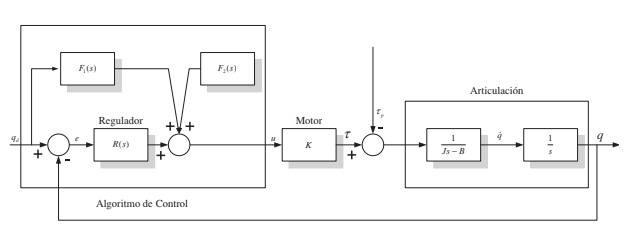

where:

- J: Inertia the actuator must overcome

- B: Viscous friction the actuator must overcome

- taup: External perturbations

#### Pre-Feeded Control

where: 

- F2(s) and R(s) are null

Scheme:

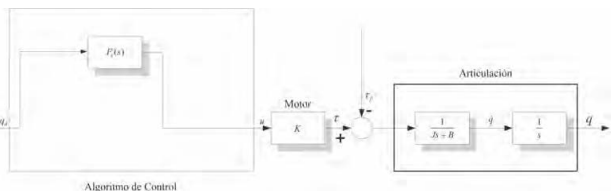

Expression: q(s) = [ K * F1(s) * qd(s) - taup(s) ] / [ J * s^2 + B * s ]

where:

- F1(s) = [ J * s^2 + B * s ] / K

Replacing:

q(s) = qd(s) - taup(s) / [ J * s^2 + B * s ]

The trayectory of the robot's articulation q will be the same as the desired trayectory qd when:

- taup(s) is null (no perturbations).

- J, B and K are precisely know.

These won't, generally, be null.

Example, where:

- taup(s) = 1/s (step function)

- qd(s) = 0

% Used in simulink
B = 5; J = 10;

#### Feedback Control

Scheme:

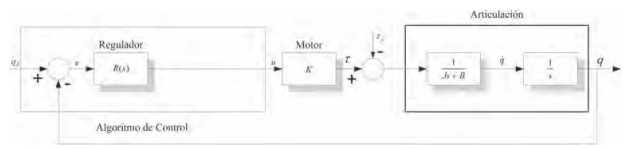

Expression: q(s) = [ K * R(s) * qd(s) - taup(s) ] / [ J * s^2 + B * s + K * R(s) ]

where:

- R(s): Can be a controller (P, PI, PD, PID)

Examples, where:

- taup(s) = 1/s (step function)

- qd(s) = 0

% Used in simulink
Kp = 5; Ki = 2;
B = 2; J = 4; K = 3;

#### Prefeeded + Feedback Control

Scheme:

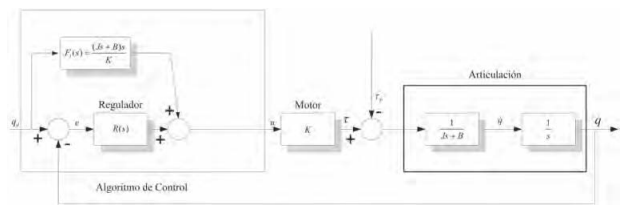

Expression: q(s) = qd(s) - taup / [ J * s^2 + B * s + K * R(s) ]

Examples, where:

- taup(s) = 1/s (step function)

- qd(s) = 0

% Used in simulink
Kp = 3; Ki = 1; Kd = 2;
B = 3; J = 1; K = 2;